# การวิเคราะห์เชิงความถี่

# ตอนที่ 2 : แนวคิดของสัญญาณรบกวน (Concept of Noise)

ในโลกความเป็นจริง** สัญญาณที่อ่านได้จากเซนเซอร์อาจโดนสัญญาณที่ไม่ต้องการเข้ามาแทรก สัญญาณนี้เรียกว่า สัญญาณรบกวน (noise)** ซึ่งสามารถเป็นลักษณะได้ทั้งในความถี่ที่ต่ำและความถี่ที่สูง โดยทั่วไปแล้ว สัญญาณรบกวนอาจจะเกิดจากการสั่นสะเทือนทางกล (mechanical vibration) หรือ การรบกวนทางแม่เหล็กไฟฟ้า (EMI, electromagnetic interference) เช่นหลอด fluorescent

ถึงแม้ว่าสัญญาณรบกวนจะไม่ใช่สัญญาณคลื่นไซน์ แต่เราสามารถจำลองสัญญาณรบกวนในรูปแบบของผลรวมของสัญญาณหลายๆอันได้ 

สัญญาณรบกวนที่มีความถี่สูง (high-frequency noise)  

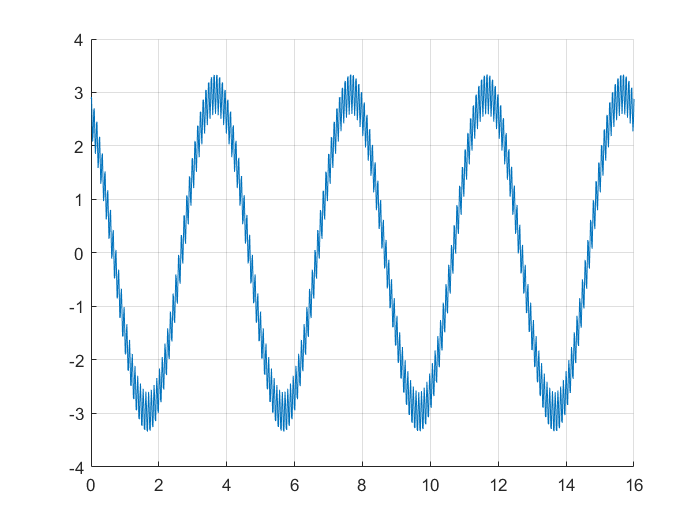

R_A = 3;
R_B = 0.4;
phi_A = pi/6;
phi_B = pi/4;
f = 0.25;
w_A = 2*pi*f;
w_B = 2*pi*f*200;
t = linspace(0,4/f,1000)';
y_A = R_A*cos(w_A*t+phi_A);
noise = R_B*cos(w_B*t+phi_B);
y = y_A+noise;
ax = axes;
hold(ax,'on')
plot(ax,t,y);
grid(ax,'on');